% demonstration code turned into live script
% constants replaced by variables when possible
clear variables
clear output
addpath(genpath(['./Library']))

## my dataset (only 1 block)

do_NF = false;
do_Deconv = true;

dirpth='./My_dataset/';
fname_prefix='QD_series_';

T=1;

## demo dataset

% NF = fspecial('gaussian',[1,21],2); % define a noise filter. 
% do_NF = true;
% do_Deconv = false;
% 
% dirpth='./Demo_dataset/';
% fname_prefix='Block';
% T=20;

% get dimensions
image_info=imfinfo([dirpth, fname_prefix, num2str(1), '.tif']);
Nframes=numel(image_info); %OR [N,]=size(image_info)
xdim=image_info(1).Height;
ydim=image_info(1).Width;
clear image_info;

## read images and calcualte M6 for each block

M6series = zeros(xdim, ydim, T);
ImMean_Series = zeros(xdim, ydim, T);
for blockN = 1 : T %for each block
    J = zeros(xdim, ydim, Nframes, 'uint16'); %create empty 3D array
    disp(['reading data and calculating M6 of block ',num2str(blockN),'/',num2str(T),'...'])
    for frameInd = 1 : Nframes %read all frames into the array
        J(:,:,frameInd) = imread([dirpth, fname_prefix, num2str(blockN),'.tif'], 'Index', frameInd);
    end
    
    %   calculate average image for this block
    ImMean_Series(:, :, blockN) = mean(double(J), 3);
    
    %   calculate M6 of this block
    M6 = zeros(xdim, ydim);
    for i0 = 1 : Nframes
        M6 = M6 + (double(J(:, :, i0)) - ImMean_Series(:, :, blockN)).^6; % directly compute. 
    end
    M6series(:, :, blockN) = M6./Nframes;
end

reading data and calculating M6 of block 1/1...


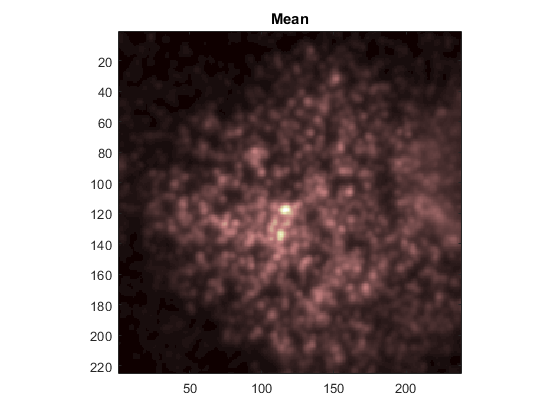

clear J;
clear M6;

%show
figure('Name', 'ImMean')
imagesc(ImMean_Series(:,:,T))
cmap = colormap(pink);
title('Mean')
axis square;

## perform noise filter along the time axis for each pixel independently and shrinking kernel deconvolution for each frame.

if do_NF
    M6_NF=my_noise_filter(M6series, NF);
else
    M6_NF=M6series;
end

if do_Deconv
    M6_NF_DeconvSK = zeros(xdim, ydim, T);
    for blockN = 1 : T
        im = M6_NF(:, :, blockN);
        % now prepare input parameters for xy_DeconvSk
        % perform mirror extension to the image in order to surpress ringing artifacts associated with fourier transform due to truncation effect.
        para.J0 = [im, fliplr(im); flipud(im), rot90(im,2)];
        % an estimation of the convolution kernel. In this datasets, cross-correlation doesn't work, therefore we use a rough estimation.
        para.PSF0 = fspecial('gaussian', [51,51], 2); 
        para.lambda = 1.5; %DeconvSK parameter
        para.ItN = 20; % iteration number.
        disp(['calculating DeconvSK on block ',num2str(blockN),'/',num2str(T),'...'])
        output = xy_DeconvSK(para);
        M6_NF_DeconvSK(:, :, blockN) = output(1:xdim, 1:ydim);
        clear output;
        clear im;
    end
else
    M6_NF_DeconvSK=M6_NF;
end

calculating DeconvSK on block 1/1...



if do_NF
    M6_NF_DeconvSK_NF=my_noise_filter(M6_NF_DeconvSK, NF);
else
    M6_NF_DeconvSK_NF=M6_NF_DeconvSK;
end

## perform LDRC on the current result

M6_LDRC_wDeconv = zeros(xdim, ydim, T);
for blockN = 1 : T
    InputImage = M6_NF_DeconvSK_NF(:,:,blockN);
    order = 7;
    Mask = ImMean_Series(:,:,blockN);
    windowSize = 25;
    disp(['calculate LDRC for frame ',num2str(blockN),'/20'])
    M6_LDRC_wDeconv(:,:,blockN) = xy_QuickLDRC(InputImage, Mask, windowSize);
end

calculate LDRC for frame 1/20


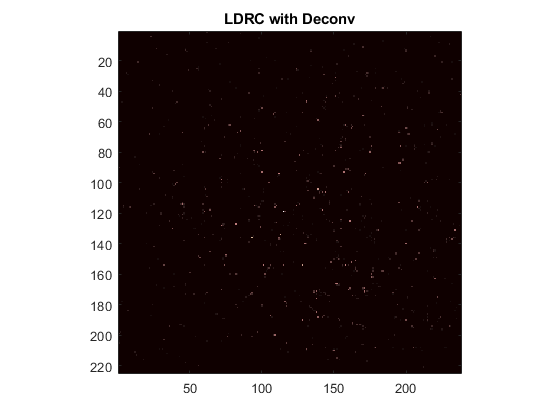


figure('Name','LDRC')
imagesc(M6_LDRC_wDeconv(:,:,T))
title('LDRC with Deconv')
axis square;
cmap = colormap(pink);


M6_LDRC = zeros(xdim, ydim, T);
for blockN = 1 : T
    InputImage = M6series(:,:,blockN);
    order = 7;
    Mask = ImMean_Series(:,:,blockN);
    windowSize = 25;
    disp(['calculate LDRC for frame ',num2str(blockN),'/20'])
    M6_LDRC(:,:,blockN) = xy_QuickLDRC(InputImage, Mask, windowSize);
end

calculate LDRC for frame 1/20


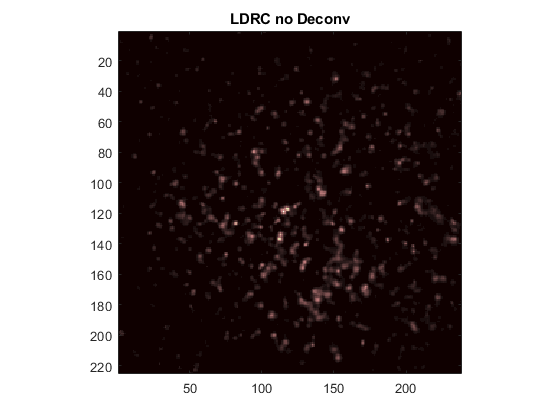


figure('Name','LDRCnoDeconv')
imagesc(M6_LDRC(:,:,T))
title('LDRC no Deconv')
axis square;
cmap = colormap(pink);

## save the result

save modular_result.mat M6_LDRC ImMean_Series

## export result as tif stack

template=[dirpth,fname_prefix];
for i0 = 1 : T
    im_in=ImMean_Series(:,:,i0);
    imwrite(im_in./max(im_in,[], 'all'), [template,'mean.tif'], 'WriteMode','append');
    im_out = M6_LDRC(:, :, i0);
    imwrite((im_out./max(im_out, [],'all')), [template,'noDeconv.tif'], 'WriteMode','append');
    im_out = M6_LDRC_wDeconv(:, :, i0);
    imwrite((im_out./max(im_out, [],'all')), [template,'wDeconv.tif'], 'WriteMode','append');
end

% Means_DeconvSK = zeros(xdim, ydim, T);
% for i0 = 1 : T
%     im = ImMean_Series(:, :, i0);
%     % now prepare input parameters for xy_DeconvSk
%         para.J0 = [im, fliplr(im); flipud(im), rot90(im,2)];% perform mirror extension to the image in order to surpress ringing artifacts associated with fourier transform due to truncation effect.
%         para.PSF0 = fspecial('gaussian', [51,51], 2); % prepare an estimation of the convolution kernel here. In this datasets, cross-correlation doesn't work, therefore we use a rough estimation.
%         para.lambda = 1.5; %DeconvSK parameter
%         para.ItN = 20; % iteration number.
%     disp(['calculating DeconvSK on image ',num2str(i0),'/',num2str(T),'...'])
%     output = xy_DeconvSK(para);
%     Means_DeconvSK(:, :, i0) = output(1:xdim, 1:ydim);
%     im1=Means_DeconvSK(:,:,i0)./max(Means_DeconvSK(:,:,i0),[],'all');
%     imwrite(im1, 'deconv_of_means.tif', 'WriteMode','append');
% end
